# How to distribute ion channels on morphologies with T2N

Note: "channel" and "distributed mechanism" are used analogous here. All distributed mechanism specifications are set in the 'mech' field of the neuron structure, where each cell/morphology has its own cell entry (e.g. {1} is the entry for the first cell). The first field then describes where the channel should be introduced and the subsequent field is the name of the channel/mechanism. T2N expects that NEURON knows this mechanism, so be sure to have the corresponding .mod files compiled, if it is a different mechanism than the standard 'pas' and 'hh' mechanism.

First we need to be sure that Matlab finds all necessary files located in the T2N and TREES folder. Caution, this code assumes that you are currently in the T2N/Tutorials folder!

if ~exist('t2n','file')         % checks if T2N is not already on the Matlab path
    if exist('t2n_Tutorial.mlx','file')  % probably you are in the t2n/Tutorials folder
        addpath(genpath(fileparts(pwd)));
    else
        error('Please run the "t2n_runthisAfterUnzip.m" script in the T2N folder or add the T2N folder including subfolders to the Matlab path!')
    end
end
if ~exist('load_tree','file')
    error('Please run the "start_trees.m" script in the TREES folder or add this folder including subfolders to the Matlab path!')
end
tree = load_tree(strrep(which('t2n'),'t2n.m','src/L5_Pyramid.mtr'));        % load an example L5 pyramidal cell from the T2N folder

## add a channel everywhere

The first possibility how to distribute a mechanism, is to put it in all sections, by using the 'all' argument in the first field. Here we distribute the passive mechanism to all regions and set the conductance 'g' and the reversal potential 'e'. For simplicity, the axial resistance 'Ra', and the membrane capacitance 'cm' are also set with the passive mechanism in T2N, as they are normally set together. The t2n_getMech function can be used to illustrate the result of distributing a mechanism parameter (here g_pas).

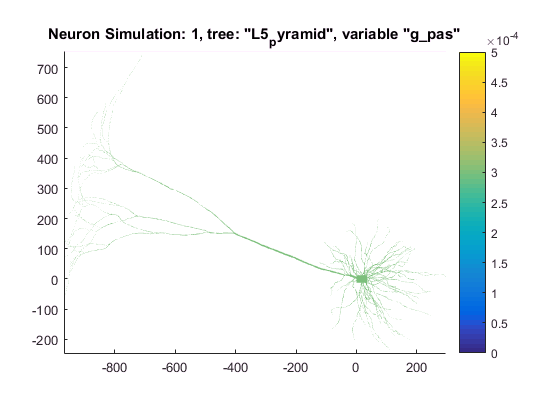

neuron.mech{1}.all.pas = struct('g',0.0003,'e',-80,'Ra',100,'cm',1);
t2n_getMech(neuron,tree,'g_pas'); set(gca,'CLim',[0 0.0005]);colorbar

## add them by their region name

The next and most commonly used option is to distribute the mechanism in a region-specific way using the region names of your TREES morphology. In the following example, it is assumed, the morphology has 3 regions called 'dendrite', 'soma' and 'axon'. Note: The possible region names of your morphology are found in tree.rnames (assumed you loaded the morphology into variable 'tree'), whereas tree.R comprises for each node the index to the rname it belongs to. Of course, more region names can be added to .rnames and indices of .R modified.

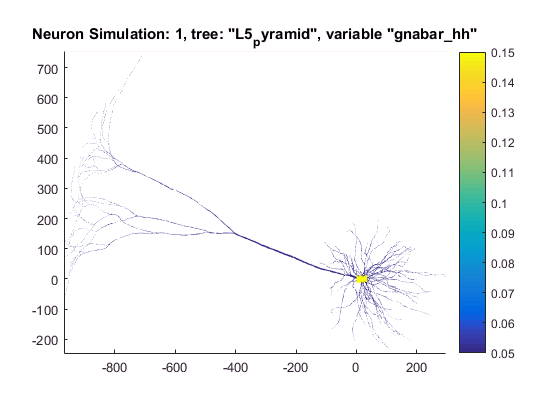

neuron.mech{1}.dendrite.hh = struct('gnabar',0.05,'gkbar',0.036,'gl',0);
neuron.mech{1}.soma.hh = struct('gnabar',0.15,'gkbar',0.036,'gl',0);
t2n_getMech(neuron,tree,'gnabar_hh'), colorbar

if these three regions are the only regions, the upper code can also be simpified by:


neuron.mech{1}.all.hh = struct('gnabar',0.05,'gkbar',0.036,'gl',0);
neuron.mech{1}.soma.hh = struct('gnabar',0.15);

This is possible because regional distribution has a higher priority than global distribution, meaning the 'gnabar' parameter of the globally  inserted hh mechanism gets subsequently overwritten by the region-specific specification, while all other set parameters of the  channel are left untouched

## applying a distance-dependent function on a channel parameter

There is one type of distribution, which has an even higher priority: the range distribution. With this feature it is possible to set a parameter of a distributed mechanism differently at each tree node. This can, for example, be used to set a distance-dependent parameter, however, in principle any function can be applied. Our example, shows how to let the hh sodium conductance decay exponentially along the dendrite

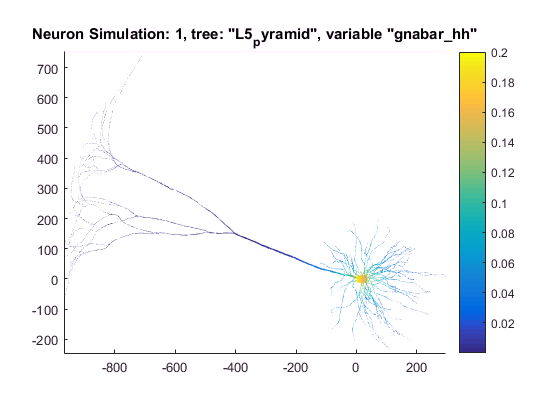


plen = Pvec_tree(tree);                                         % get path lengths to root for each node
vec = 0.2*exp(-plen/100);                                       % create the exponentially decaying range vector for the hh sodium conductance
isdendritic =  find(strcmp(tree.rnames,'dendrite'));            % get the region index of the 'dendrite' region
isdendritic = tree.R == isdendritic;                            % get the nodes that belong to this region
vec(~isdendritic) = NaN;                                        % let only the dendritic regions be exponentially decaying and keep the standard value(s) for the rest by setting their range entry to NaN
neuron.mech{1}.range.hh = struct('gnabar',vec);                 % set the range variable

t2n_getMech(neuron,tree,'gnabar_hh'), colorbar

T2N then sets the variable at each location on the morphology where it is non-NaN in the vector. Generally, this feature should only be used when it is really necessary and not doable by a finer specification of regions (e.g. defning an axon initial segment region instead of increasing sodium conductance of the proximal part of the axon) because T2N has to write every value with its location to a file, which is then read by NEURON. This can be quite time consuming for many and/or large morphologies.

Note: The outcome of this feature can strongly depend on the number of segments, which are set for the morphology, because the more segments are used per section, the finer is the spatial resolution of the ranged parameter. Otherwise, if two values fall into the same segment, T2N calculates the mean (ignoring NaNs) of both, which makes the resolution coarser.